## How to properly tweak envelopes

### The ABC

Focus on the attack first, since the decay and release curves are "inverted" attack, with a range.

Need to define a clean attack that leverages from few micro-secronds (the *anti-glitch* minimum time) to 10 seconds.

In this document we will consider:

global sampling_freq
sampling_freq_khz = 48;
sampling_freq = sampling_freq_khz * 1000;
global atk_min
atk_min = 10;
global atk_max
atk_max = 10 * sampling_freq;
titles = ["Sampling frequency (kHz)" ; "min attack time (ticks)" ; "max attack time (ticks)"];
values = [sampling_freq_khz ; atk_min ; atk_max];
for i = 1:3
    fprintf("%s = %d\n", titles(i), values(i));
end

Sampling frequency (kHz) = 48
min attack time (ticks) = 10
max attack time (ticks) = 480000


Need to design a clean attack envelope, with respect to ear's perception, which is basically logarithmic.

The raw curve is given by the *cincr* function, that increments the amplitude at every tick:


$$A=A_{\max } \;\left(1-e^{-\;\frac{t}{T}} \right)$$


Where:

- $A_{\max } \;$is the maximum amplitude (i.e. 1 for an attack if the volume leverages from 0 to 1

- $t$is the current tick, from 0 to the duration (in samples) of the attack (named *atk* in this study)

- $T$ defines the *aggressivity* of the curve, the lower the more aggressive

Intuitively, for very short attacks, we need a very low value for $T$ and a much bigger for slow attacks:


$$T=\phi \left(\textrm{atk}\right)$$


function y = cincr0(t, tau, amax)
    y = single(amax * (1 - exp(-t/tau)));
end

For example, given $\phi \left(x\right)=x$, the attack curves for different attack durations are:

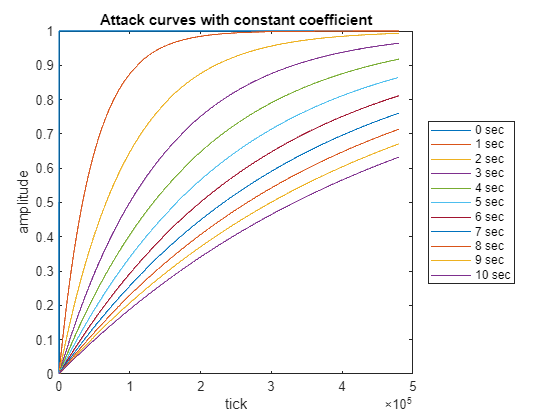

ticks = linspace(0, atk_max, atk_max);
cur = strings(0);
out = [];
for atk_sec = 0:10
    max_tick = max(atk_min, sampling_freq * atk_sec);
    cur(end + 1) = int2str(atk_sec) + " sec";
    out(end + 1, :) = cincr0(ticks, max_tick, 1);
end
[nlines, ~] = size(out);
for i = 1:nlines
    plot(out(i, :), 'DisplayName', cur(i));
    hold on;
end
hold off;
legend(cur, 'Location', 'eastoutside');

xlabel('tick');
ylabel('amplitude');
title("Attack curves with constant coefficient");

Clearly, the figure above shows that $T=\phi \left(\textrm{atk}\right)$ is not a good choice: for long attacks, the curve is to "linear" and does not reach the expected maximum.

### Perceptive considerations

Considering ampitudes in this scope implies thinking in subtracting decibels rather than adding. In other words, an amplitude of 1 is the maximum volume that can be reached, whereas 0 means "removing enough dB to get an unperceptible sound".

Empirically, **-40dB** is a good threshold to consider that the output is almost silent.

We want to get attacks that:

- Grow very fast at the beggining

- Become much flatter when reaching the asymptotic value of 1

We may consider **-6dB** and **-3dB** as well-known remarkable points to tune the attack curve.

Practically, it means:

- Identifying noticeable ticks $t_0$, $t_1$... and the amount of decibels $d_i$ to remove from the maximum amplitude $A_{\max }$

- Defining the target amplitude at each point: $A_i \approx A_{\max } \;{10}^{-\;\frac{d_i }{20}}$

Given that $t_i$ is estimated as a percentage of the total attack $\textrm{atk}$.

For example:

function [ti,Ai] = db_loss_example(percent_tick, dbs, atk_ticks)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



    global sampling_freq
    A_max = 1;         % Amplitude from 0 to 1

0.100000 5.000000


    ti = percent_tick * atk_ticks / 100;
    Ai = db_loss(dbs, A_max);

1 percent, -40dB : 0.100000 0.010000
    0.1000



end
A = [ db_loss_example(1, 40, atk_min) ; db_loss_example(50, 6, atk_min) ; db_loss_example(80, 3, atk_min) ; db_loss_example(99, 0.1, atk_min)];
fprintf("%f %f\n", A(1), A(2));
[t1,A1] = db_loss_example(1, 40, atk_min);
fprintf('%d percent, -%ddB : %f %f\n', 1, 40, t1, A1); disp(db_loss_example(1, 40, atk_min));

For a given target amplitude $A$ that must be reached at a given tick $t$, one can compute the corresponding value of $T$: 


$$A=A_{\max } \;\left(1-e^{-\;\frac{t}{T}} \right)\Rightarrow e^{-\;\frac{t}{T}} =1-\frac{A}{A_{\max } }\Rightarrow T=-\frac{t}{\ln \left(1-\frac{A}{A_{\max } }\right)}$$


COMMON FUNCTIONS TODO (yeah I know it's a bad practice)

function ai = db_loss(dbs, max_amp)
    ai = max_amp * power(10, -dbs / 20);
end